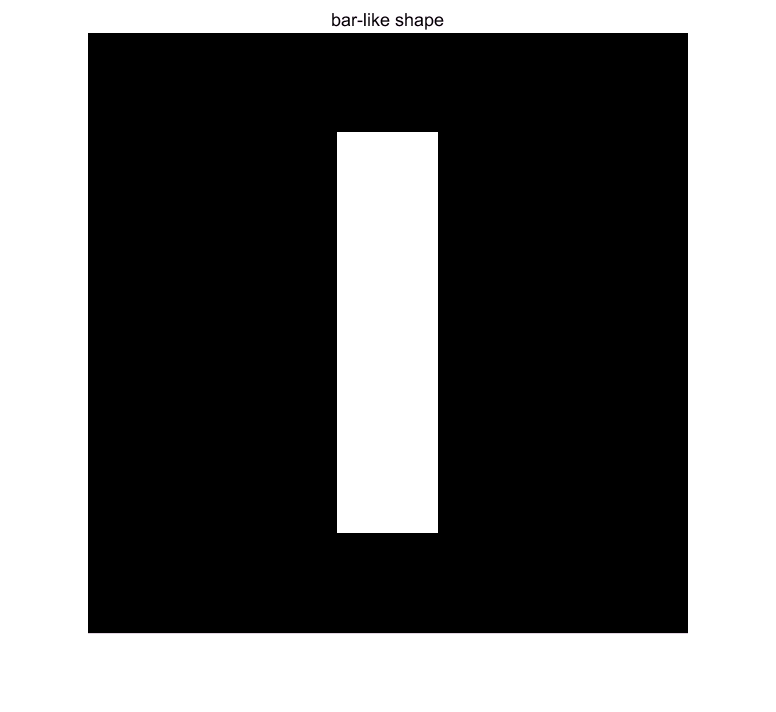

g1 = zeros(600, 600);
g1(100:500, 250:350) = 1;  %% obtain a bar-shape image
g2 = phantom('Modified Shepp-Logan');  %% create a Shepp-Logan phantom 
                                      %% with default size 256x256
imshow(g1), title('bar-like shape');

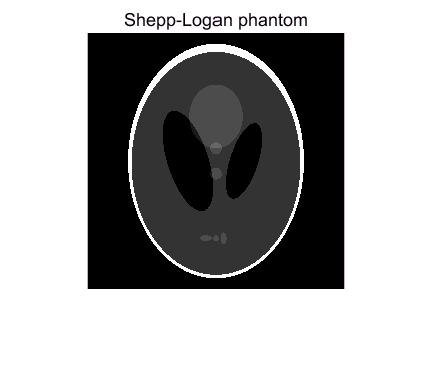

figure, imshow(g2), title('Shepp-Logan phantom');

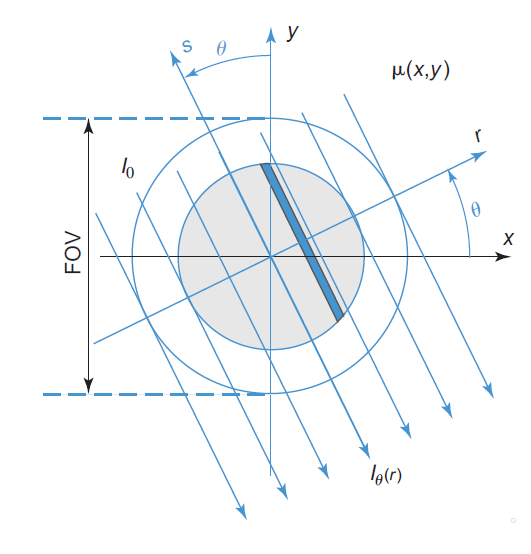

                                                        Radon transform schematic   


$$p(r,\theta) = \mathcal{R}\{f(x,y)\} = \int_{-\infty}^{\infty}{f(r\cdot cos\theta - s\cdot sin\theta, r\cdot sin\theta + s\cdot cos\theta)ds} $$


FOV: Field of View

%% Radon transform at half degree interval
theta = 0:0.5:179.5;
[R1_org, xp1] = radon(g1, theta);
[R2_org, xp2] = radon(g2, theta);

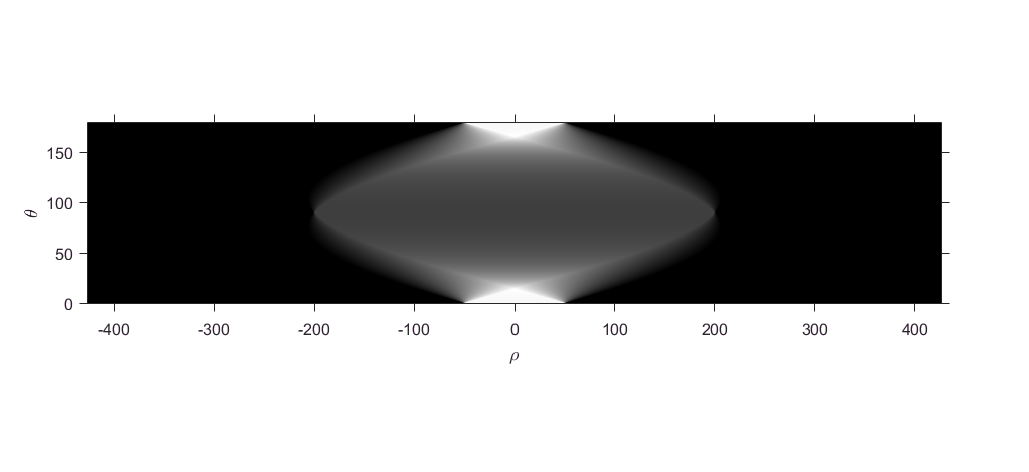

%% flip and transpose the R matrix
R1 = flipud(R1_org');
R2 = flipud(R2_org');
figure, imshow(R1, [], 'XData', xp1([1 end]), 'YData', [179.5 0]);
axis xy;
axis on;
xlabel('\rho'), ylabel('\theta');

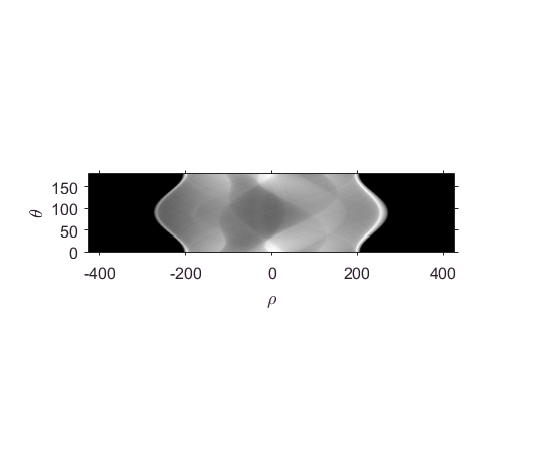

figure, imshow(R2, [], 'XData', xp1([1 end]), 'YData', [179.5 0]);
axis xy;
axis on;
xlabel('\rho'), ylabel('\theta');

Three ways to reconstruct a 2D image (inverse radon transform)

1. Back Projection

2. Direct Fourier Reconstruction

3. Filtered Back Projection

**1. Back Projection**

Assign value $p(r,\theta)$ to all points $(x,y)$ along that line, so a point $(x,y)$ would take the summation of all the lines ($xcos\theta + ysin\theta = r$) crossing it.

For $\theta_1$, the line crossing point $(x,y)$ would be $x\cdot cos\theta_1 + y\cdot sin\theta_1 = r_1$, and the intensity would be $p(r_1, \theta_1)$. 

Similarly, for $\theta_2
$, the line crossing point $(x,y)$ would be $x\cdot cos\theta_2 + y\cdot sin\theta_2 = r_2$, and the intensity would be $p(r_2, \theta_2)$.

For $\theta_n$, the line crossing point $(x,y)$ would be $xcos\cdot \theta_n + y\cdot sin\theta_n = r_n$, and the intensity would be $p(r_n, \theta_n)$.

And the point $(x,y)
$ in the reconstructed image would take the intensity     

                                                 $\lim\limits_{i\to + \infty}\sum {p(r_i, \theta_i)} = \int_{0}^{\pi}{p(r^{*}, \theta)}d\theta $.

Thus, the formula for direct back projection is 


$$b(x,y) = \mathcal B\{p(r,\theta)\} = \int_{0}^{\pi}{p(r, \theta)}d\theta =  \int_{0}^{\pi}{p(x\cdot cos\theta + y\cdot sin\theta, \theta)}d\theta$$


Only one half of the rotation is needed, thus the integral only considers the interval $[0,\pi)$.

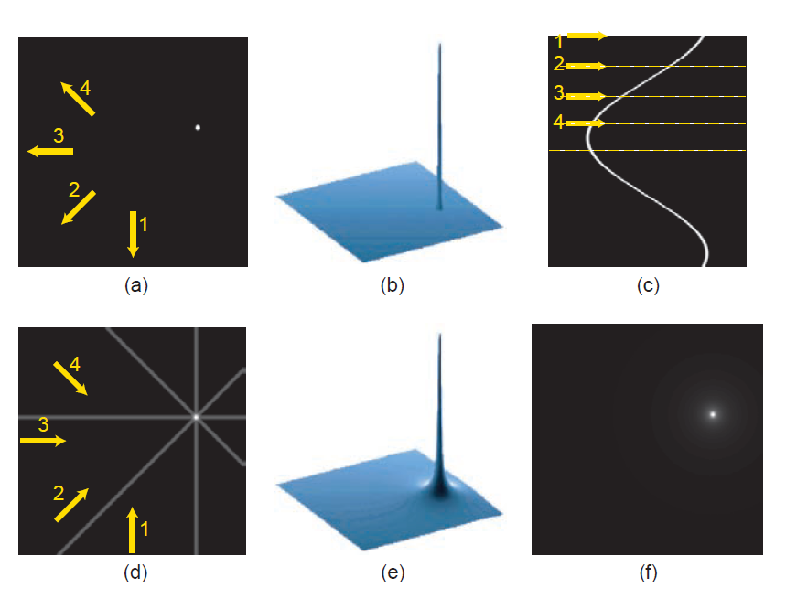

**2. Direct Fourier Reconstruction**

*Central Slice Theorem*

The 2D Fourier Transform of the original 2D image $f(x,y)$ is


$$F(k_x, k_y) = \mathcal{F}\{f(x,y)\} = \int_{-\infty}^{\infty}\int_{-\infty}^{\infty}{f(x,y)e^{-j2\pi({k_x}x+{k_y}y)}dxdy$$


The 1D Fourier Transform of $p(r, \theta)$ with respect to $r$ at angle $\theta$ is


$$P_\theta(k) = \int_{-\infty}^{\infty}{p(r, \theta)e^{-j2\pi kr}}dr$$


Expand this single variate function into a dual variate function $P(k, \theta)$

The **central slice theorem** states that


$$P(k,\theta) = F(k_x, k_y)$$


Provided that


$$\left\{
\begin{array}{rcl}
k_x = & k\cdot cos\theta   \\
k_y = & k\cdot sin\theta    \\
k = & \sqrt{{k_x}^2+{k_y}^2} 
\end{array} \right$$


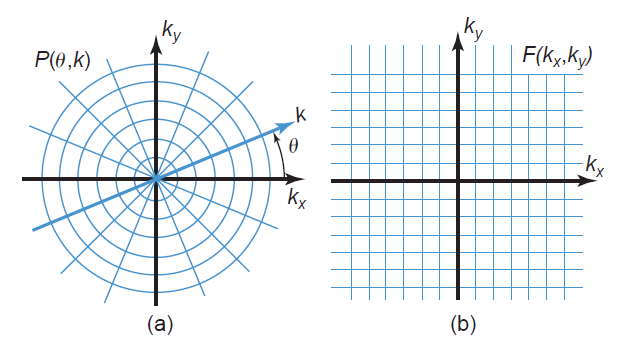 

In discrete form, interpolation should be exercised to fill the values not assigned directly from the polar grid.

*Direct Fourier Reconstruction*

S1 Calculate $P_\theta(k) = \mathcal{F}_1\{p(r, \theta)\} $ for all angles, stack these functions into $P(k, \theta)$

S2 Convert $P(k,\theta) $ to $F(k_x, k_y)$ using interpolation from polar grid to rectangular grid

S3 Calculate the IFT of $F(k_x, k_y)$ to obtain $f(x,y)$,$\mathcal{F}_2^{-1}\{F(k_x, k_y)\} = f(x,y)$

Attention: The interpolation in S2 could cause artifact in the reconstructed image. Thus, direct fourier reconstruction is rarely used in reality.

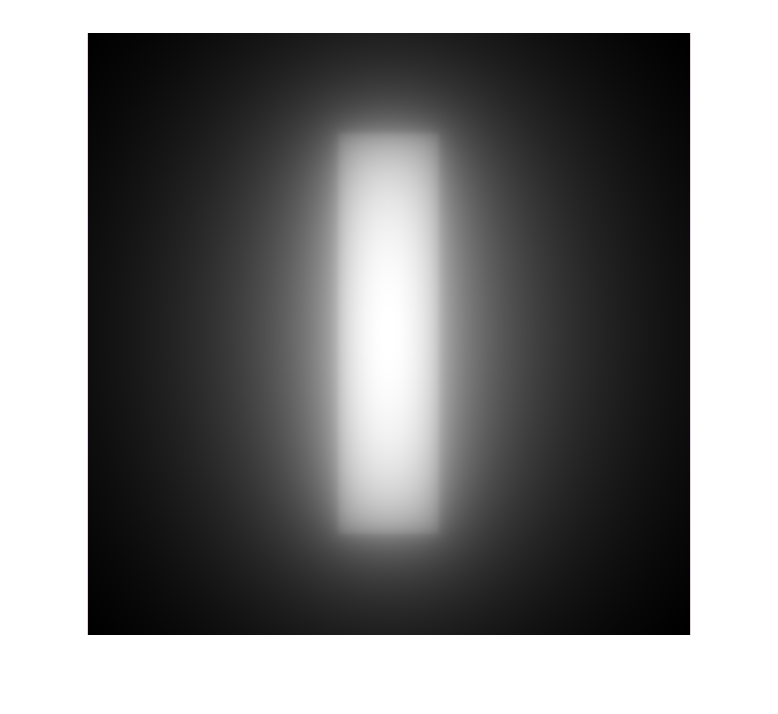

%% Direct Fourier Reconstruction
f1_d = iradon(R1_org, theta, 'spline', 'none');
f2_d = iradon(R2_org, theta, 'spline', 'none');
figure, imshow(f1_d, []);

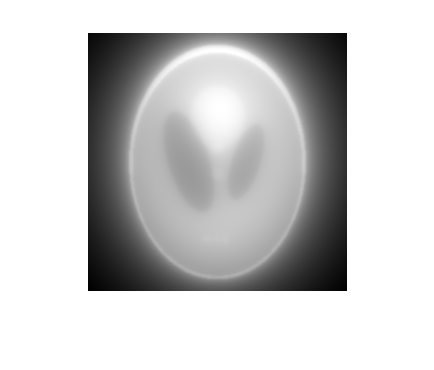

figure, imshow(f2_d, []);

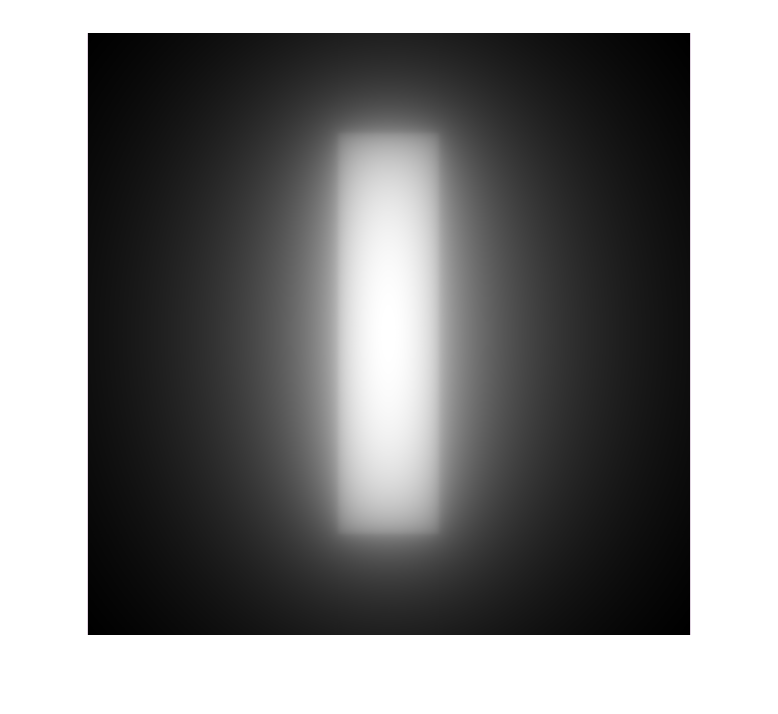

%% Different interpolation
%% Almost no difference?
f1_d_nearest = iradon(R1_org, theta, 'nearest', 'None');
f1_d_linear = iradon(R1_org, theta, 'linear', 'None');
f1_d_cubic = iradon(R1_org, theta, 'cubic', 'None');
f1_d_spline = iradon(R1_org, theta, 'spline', 'None');
figure('Name', 'nearest', 'NumberTitle','off'), imshow(f1_d_nearest, []);

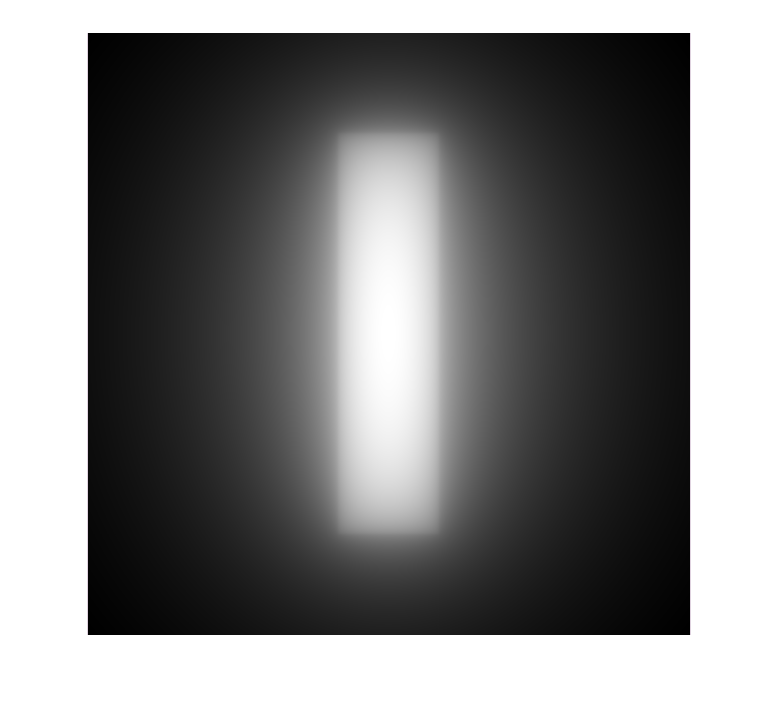

figure('Name', 'linear', 'NumberTitle','off'), imshow(f1_d_linear, []);

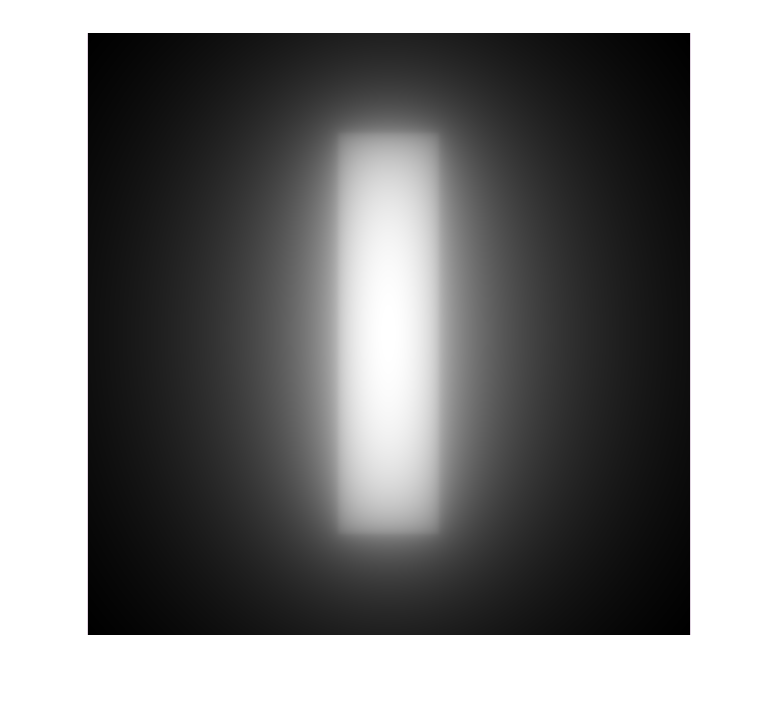

figure('Name', 'cubic', 'NumberTitle','off'), imshow(f1_d_cubic, []);

figure('Name', 'spline', 'NumberTitle','off'), imshow(f1_d_spline, []);

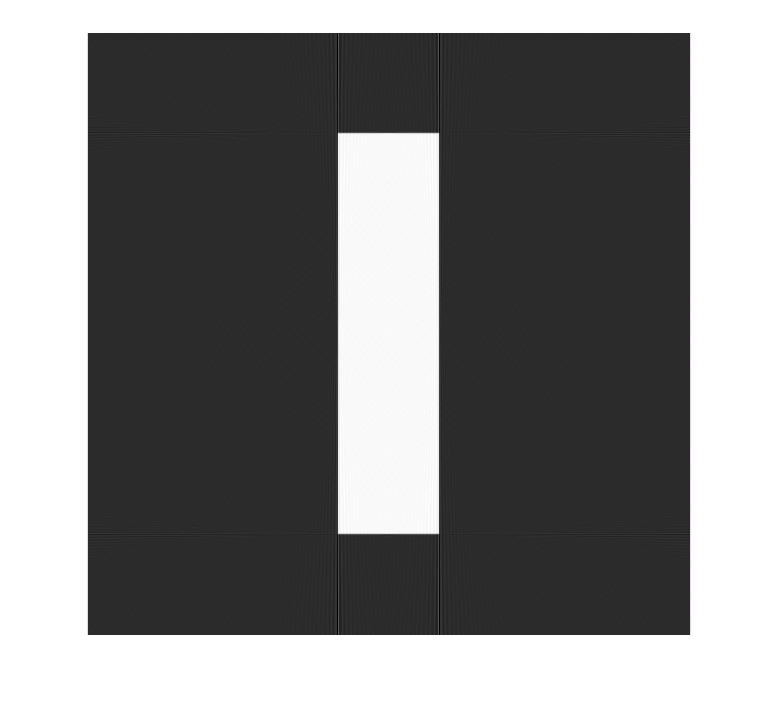

%% Applying Ram-Lak filter for reconstruction
f1_ram = iradon(R1_org, theta, 'Ram-Lak');
f2_ram = iradon(R2_org, theta, 'Ram-Lak');
figure, imshow(f1_ram, []);

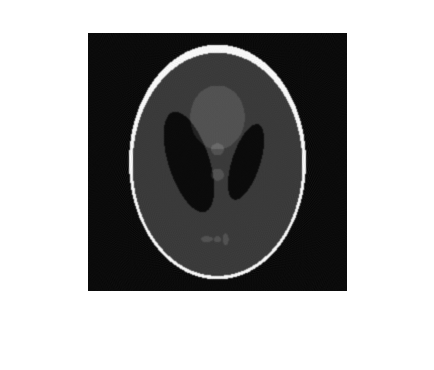

figure, imshow(f2_ram, []);

1. Ram-Lak filter would casue ripples in the reconstructed image.

2. Ram-Lak filter would cause images to have a grayish tone due to the negative values produces and scaling(negative -> average to move up after scaling).

3. These situations could be substantially improved by using other filters.

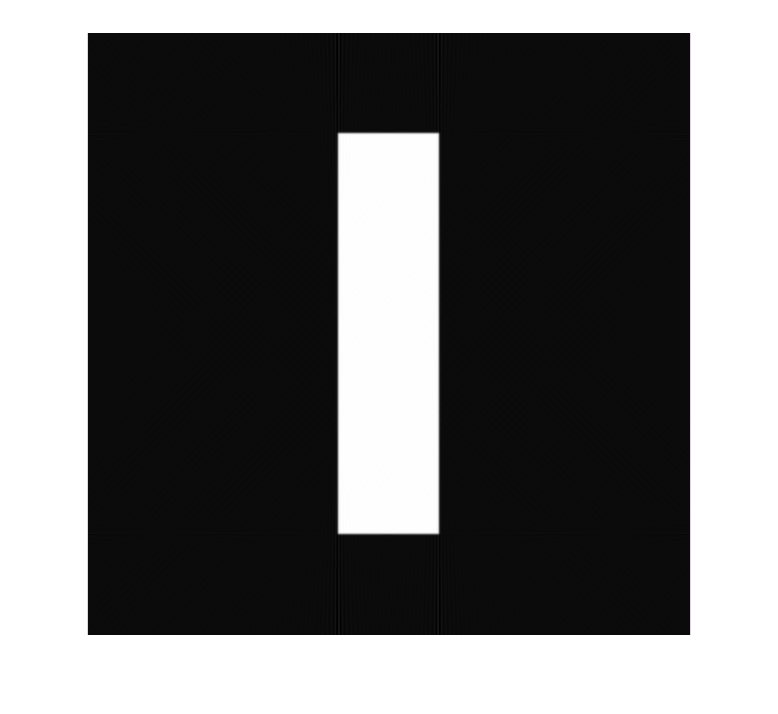

%% Hann window
f1_hann = iradon(R1_org, theta, 'Hann');
f2_hann = iradon(R2_org, theta, 'Hann');
figure, imshow(f1_hann, []);

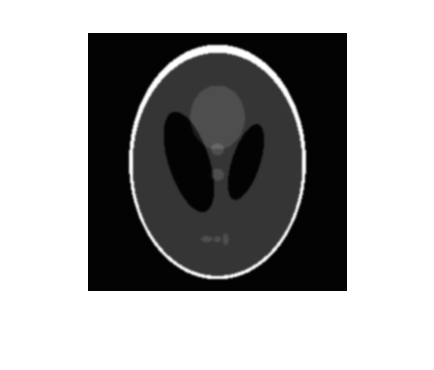

figure, imshow(f2_hann, []);

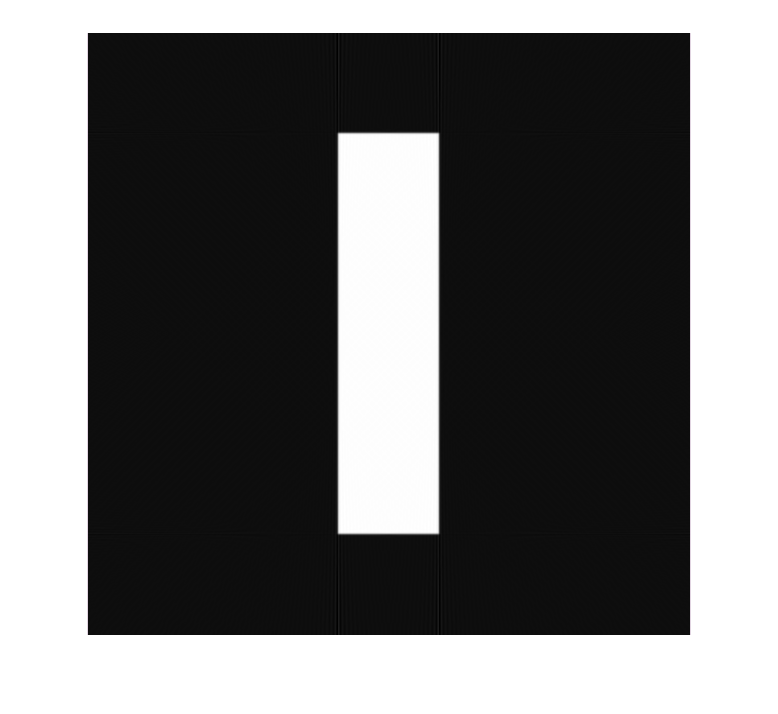

%% Use Hamming window to improve the quality of reconstructed image
f1_hamm = iradon(R1_org, theta, 'Hamming');
f2_hamm = iradon(R2_org, theta, 'Hamming');
figure, imshow(f1_hamm, []);

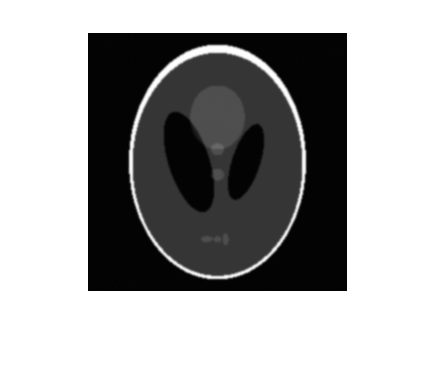

figure, imshow(f2_hamm, []);

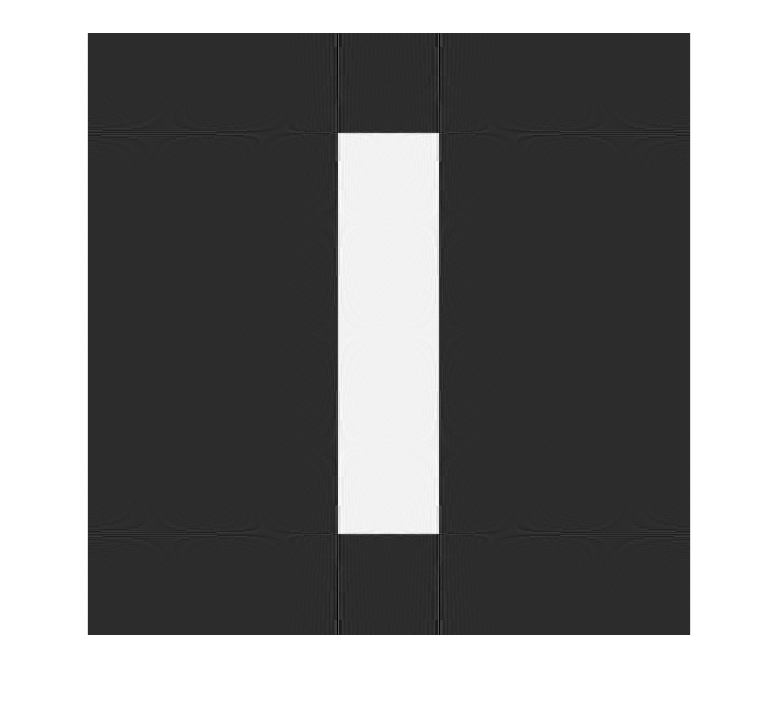

%% different interpolation could have different impact on the reconstruction
f1_near = iradon(R1_org, theta, 'nearest');
f1_lin = iradon(R1_org, theta, 'linear');
f1_cub = iradon(R1_org, theta, 'cubic');
figure, imshow(f1_near, []);

figure, imshow(f1_lin, []);

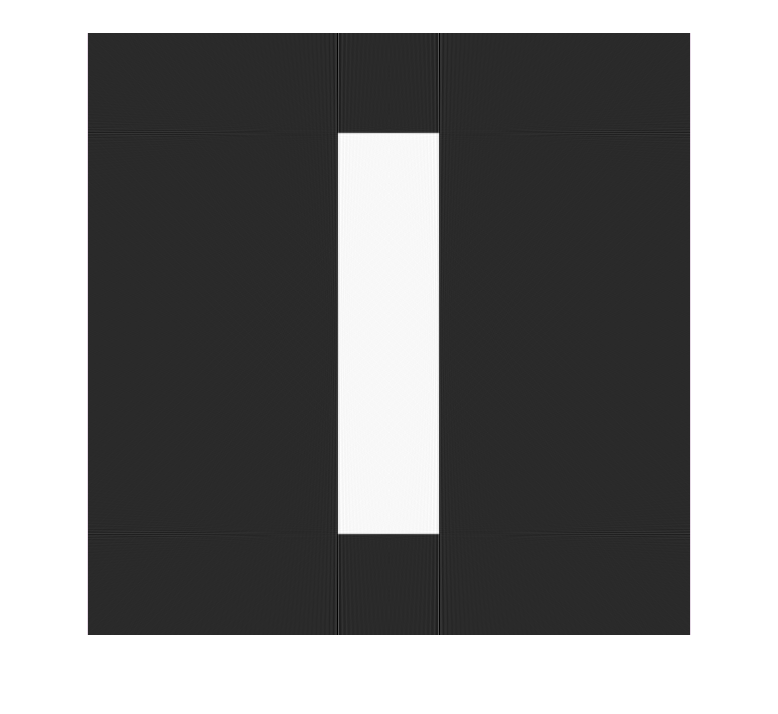

figure, imshow(f1_cub, []);

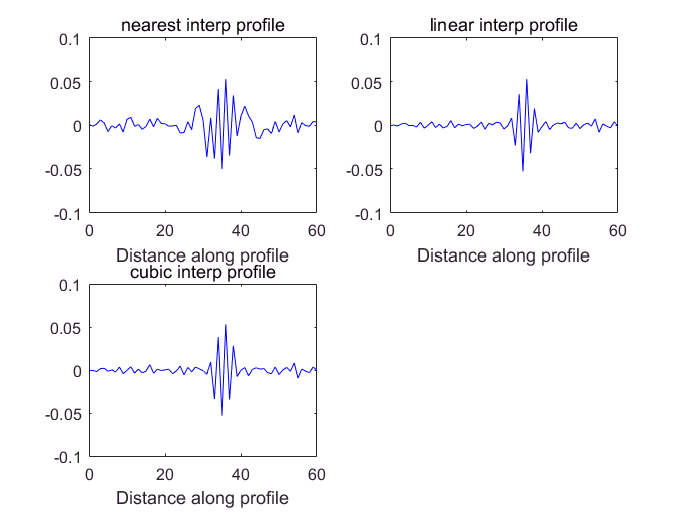

% check the profile at the up right ripple
subplot(2,2,1), improfile(f1_near, [550 550],[65, 125]), title('nearest interp profile');

subplot(2,2,2), improfile(f1_lin, [550 550],[65, 125]), title('linear interp profile');
subplot(2,2,3), improfile(f1_cub, [550 550],[65, 125]), title('cubic interp profile');

Before jump into fan-beam geometry, revise the filtered back projection reconstruction steps.

1. $P^*(k, \theta) = P(k, \theta) \cdot Q(k)$, $p^*_{\theta}(r) = \mathcal F^{-1}\{P^*_{\theta}{(k)}\}$, and $p^*(r, \theta)$ are stacked from all the IFT at all angles. $Q(k)$ is the response function of the filter.

2. Back projection. $f(x,y) = \int_0^\pi{p^*(r, \theta)}d\theta$

The filtering procedure in time-domain:


$$p_\theta^*(r) = \int_{-\infty}^{\infty}{p_\theta(r')\cdot q(r-r')}dr'$$


This is for one angle, and the final two dimension $p(r, \theta)$ requires all the 1D functions of all the angles to be stacked together.

Now, jump into the fan beam geometry

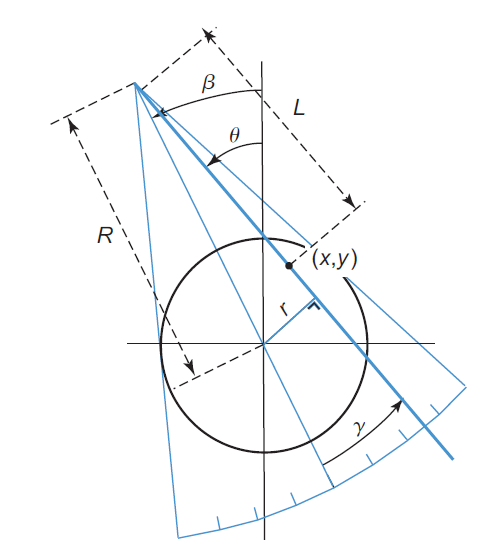

Fan beam use two variables, $\gamma$ and $\beta$ to represent the coordinates. The tramsform from $(r, \theta)$ to $(\gamma, \beta)$ is 


$$\left\{\begin{array}{rcl}
r = & Rsin\gamma \\
\theta = & \beta + \gamma
\end{array}\right$$


For parallel coordinates, 


$$f(x,y) = \frac{1}{2}\int_0^{2\pi}{\int_{-\frac{FOV}{2}}^\frac{FOV}{2}p(r', \theta)\cdot q(xcos\theta+ysin\theta-r')dr'}d\theta$$


Here, 1/2 is used to compensate the entire round of the rotation, in usual case, only 

one half of rotation is required for the integral.

After transformation,


$$f(x,y) = \frac{1}{2}\int_0^{2\pi}{\int_{-\frac{fan-angle}{2}}^{\frac{fan-angle}{2}}p(\gamma',\beta)\cdot q(xcos(\gamma+\beta)+ysin(\gamma+\beta)-Rsin\gamma')Rcos\gamma'd\gamma'}d\beta$$


fan-angle is the angle spanned by the fan, $\frac{fan-angle}{2} = arcsin\left(\frac{r}{(FOV/2)}\right)$.

The above equation can be converted into the following form


$$f(x,y) = \int_0^{2\pi}\frac{1}{L^2}\int_{-\frac{fan-angle}{2}}^{\frac{fan-angle}{2}}[Rcos\gamma'p(\gamma', \beta)]\cdot 
\frac{1}{2}\left(\frac{\gamma-\gamma'}{sin(\gamma-\gamma')}\right)q(\gamma-\gamma')d\gamma'd\beta
       $$


If the detectors are located on a flat panel instead of an arc one, then the geometry could be

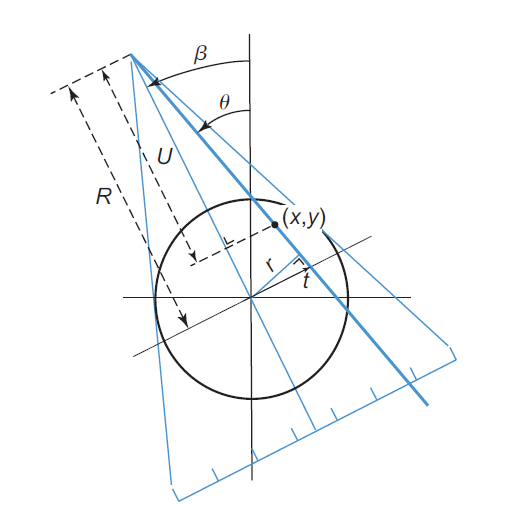

In this case, the coordinate $(t, \beta)$ is used where $t$ is the distance from the origin to the ray through$(x,y)$ measured parallel to the detector panel.

The reconstruction formula would be


$$f(x,y) = \int_0^{2\pi}\frac{1}{(U/R)^2}\int_{-\infty}^{\infty}[\frac{R}{\sqrt{R^2+t^2}}\cdot p(t', \beta)]\cdot \frac{1}{2}q(t-t')dt'd\beta$$


The above calculation of the formula can be reference in the book 

*A. C. Kak and M. Slaney. **Principles of Computerized Tomographic Imaging**. New York: IEEE Press, 1987.*

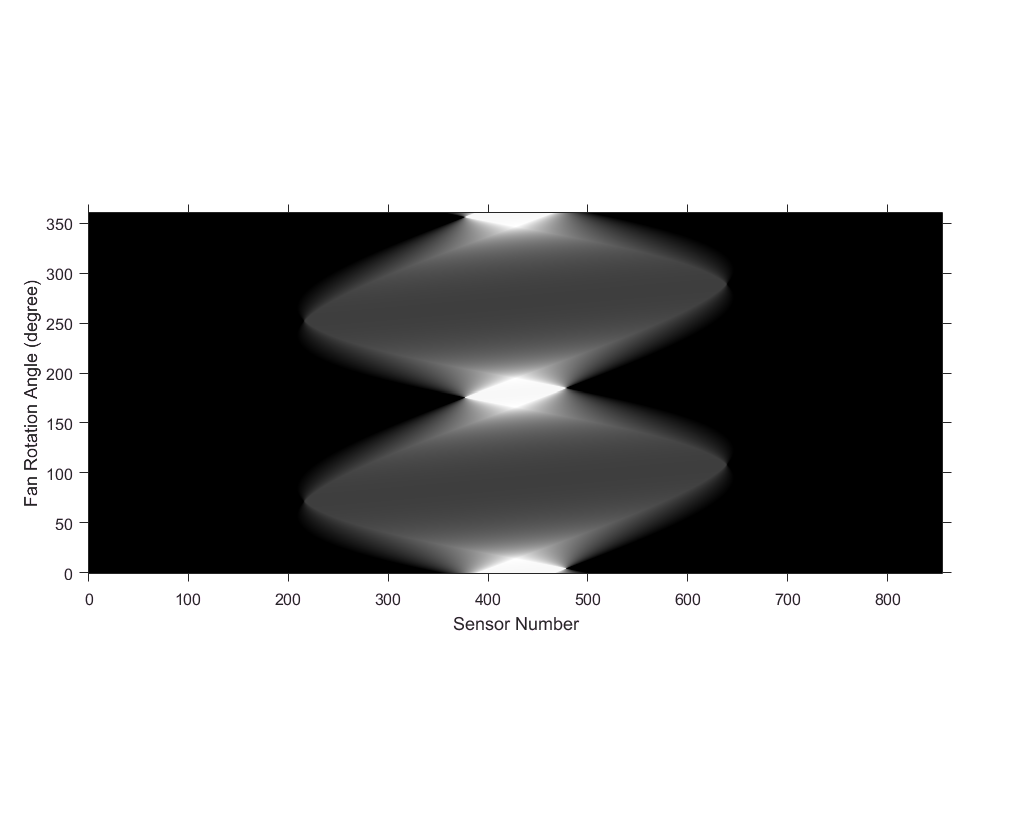

%% Fan Beam FBP
% Line geometry
g1 = zeros(600, 600);
g1(100:500, 250:350) = 1;
g2 = phantom('Modified Shepp-Logan', 600);

D = 1.5*hypot(size(g1, 1), size(g1, 2))/2;  % hypot calculates the square root of the sum of squares
                                            % D is the distance between the beam source and the coordinates origin. 
                                            % D should be larger than the half of FOV. In this case, the hypotenuse.

% In this cell, the line geometry is applied, while the arc geometry is applied next
B1_line_org = fanbeam(g1, D, 'FanSensorGeometry', 'line', 'FanSensorSpacing', 1, 'FanRotationIncrement', 0.5);
% FanSensorSpacing determines the distance between two sensors in the detector panel(since this case)
% the geometry is line; 
% FanRotationIncrement determines the intervals between two rotation angle of the fan beam,
% which is the beta in the above schematics.
% The number of sensors would be computed by the method to guarantee that in any rotation angle, the whole image 
% would be covered by all the detectors.
B1_line = flipud(B1_line_org');
B2_line_org = fanbeam(g2, D, 'FanSensorGeometry', 'line', 'FanSensorSpacing', 1, 'FanRotationIncrement', 0.5);
B2_line = flipud(B2_line_org');
figure, imshow(B1_line, [], 'XData', [0 size(B1_line, 2)], 'YData', [360 0]);
axis xy;
axis on;
xlabel('Sensor Number'), ylabel('Fan Rotation Angle (degree)');

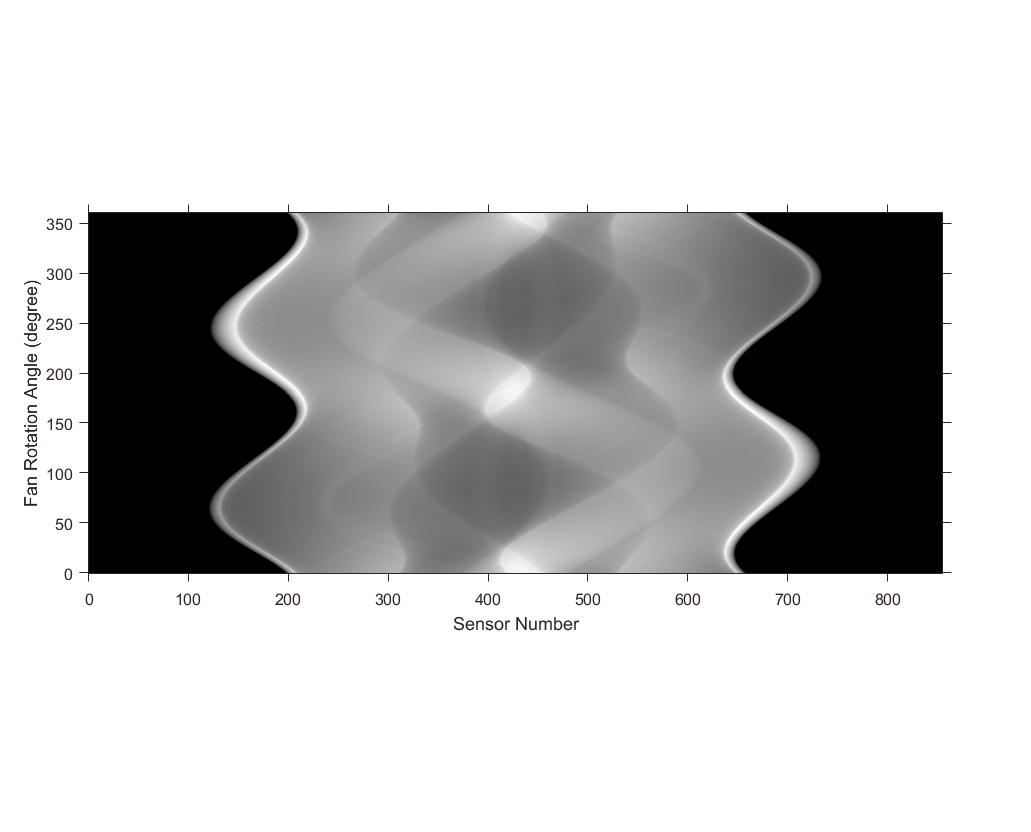


figure, imshow(B2_line, [], 'XData', [0 size(B1_line, 2)], 'YData', [360 0]);
axis xy;
axis on;
xlabel('Sensor Number'), ylabel('Fan Rotation Angle (degree)');

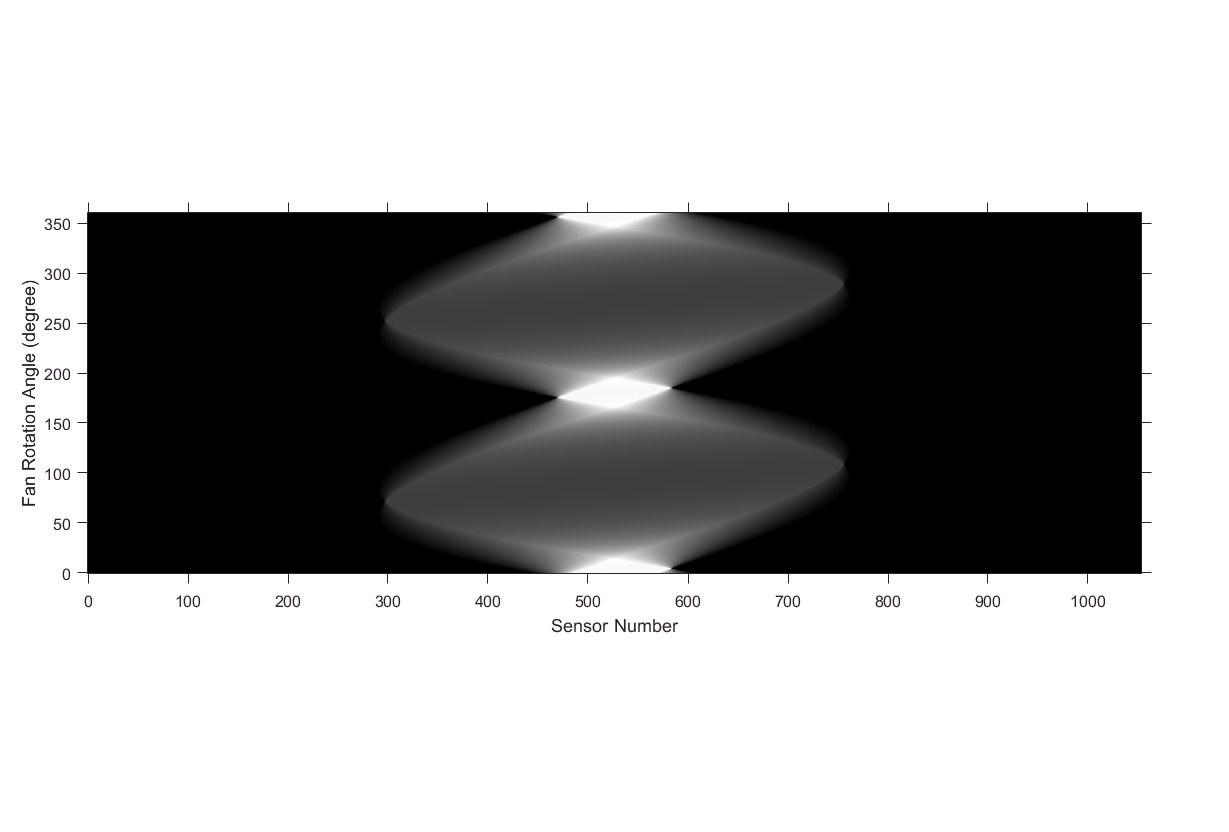

% For different geometry, the generated sinogram would possess distinct sizes.
% Arc geometry
% Here, the FanSensorSpacing is 0.08 in an effort to make the generated sinogram's size as close as the previous ones
B1_arc_org = fanbeam(g1, D, 'FanSensorGeometry', 'arc', 'FanSensorSpacing', 0.08, 'FanRotationIncrement', 0.5);
B2_arc_org = fanbeam(g2, D, 'FanSensorGeometry', 'arc', 'FanSensorSpacing', 0.08, 'FanRotationIncrement', 0.5);
B1_arc = flipud(B1_arc_org');
B2_arc = flipud(B2_arc_org');
figure, imshow(B1_arc, [], 'XData', [0 size(B1_arc, 2)], 'YData', [360 0]);
axis xy;
axis on;
xlabel('Sensor Number'), ylabel('Fan Rotation Angle (degree)');

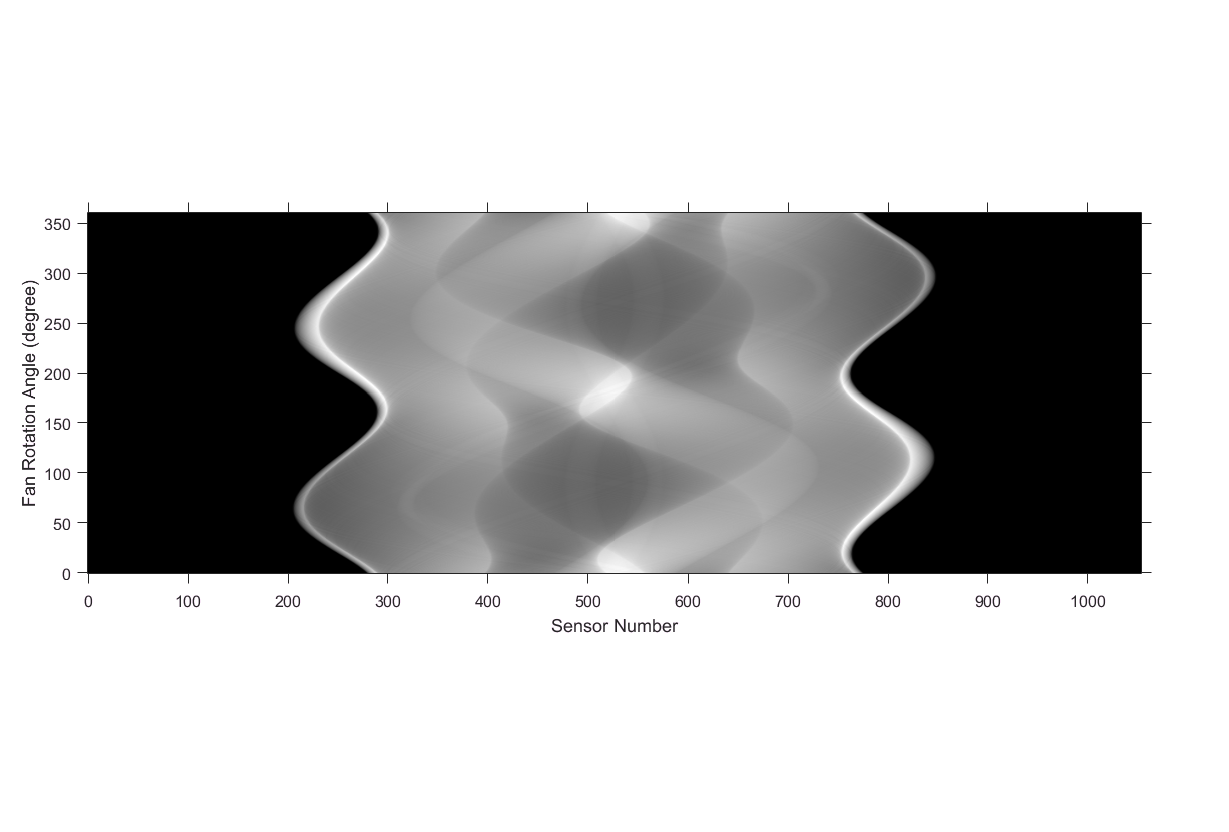


figure, imshow(B2_arc, [], 'XData', [0 size(B2_arc, 2)], 'YData', [360 0]);
axis xy;
axis on;
xlabel('Sensor Number'), ylabel('Fan Rotation Angle (degree)');


$$f(x,y) = \frac{1}{2}\int_0^{2\pi}{\int_{-\frac{fan-angle}{2}}^{\frac{fan-angle}{2}}p(\gamma',\beta)\cdot q(xcos(\gamma+\beta)+ysin(\gamma+\beta)-Rsin\gamma')Rcos\gamma'd\gamma'}d\beta$$


According to the equation above, the reconstruction requires a filter to impair the artifact from direct projection. The filters, again, are included in the parameter of ifanbeam.  Default filter is Ram-Lak.

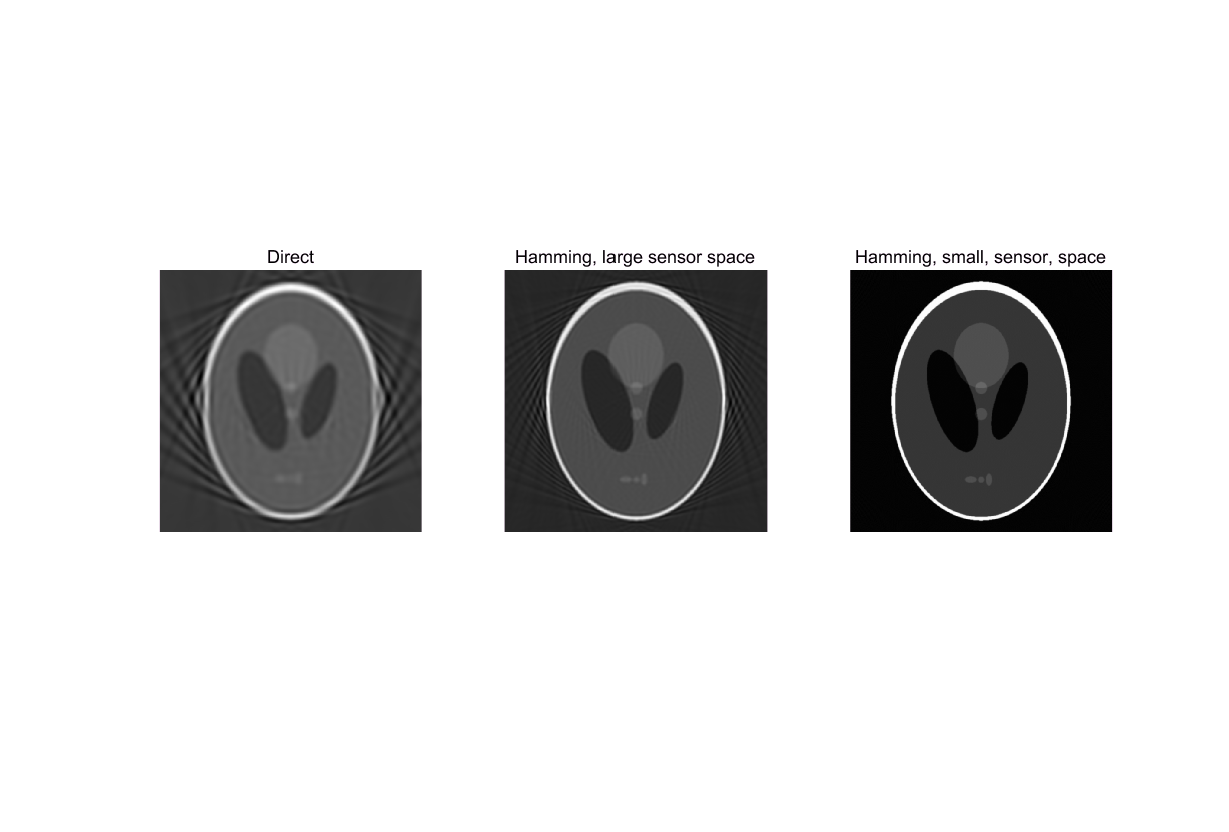

% Default value for fanbeam and ifanbeam, Ram-Lak is the default filter
default_B2 = fanbeam(g2, D);
default_fB2 = ifanbeam(default_B2, D);

% Using Hamming filter to impair the artifact
Hamm_B2 = fanbeam(g2, D, 'FanRotationIncrement', 0.5, 'FanSensorSpacing', 0.5);
Hamm_fB2 = ifanbeam(Hamm_B2, D, 'FanRotationIncrement', 0.5, 'FanSensorSpacing', 0.5, 'Filter', 'Hamming');

% Using Hamming filter with smaller sensor spacing to refine the image
Hamm_B2_fine = fanbeam(g2, D, 'FanRotationIncrement', 0.5, 'FanSensorSpacing', 0.05);
Hamm_fB2_fine = ifanbeam(Hamm_B2_fine, D, 'FanRotationIncrement', 0.5, 'FanSensorSpacing', 0.05, 'Filter', 'Hamming');

subplot(1, 3, 1), imshow(default_fB2, []), title('Direct');
subplot(1, 3, 2), imshow(Hamm_fB2, []), title('Hamming, large sensor space');
subplot(1, 3, 3), imshow(Hamm_fB2_fine, []), title('Hamming, small, sensor, space');

It is noticed that, with the sampling rate increased (sensor spacing decreased), and more practical filter applied, the quality of the reconstructed image is higher.

Matlab also provides two powerful functions to convert the sinogram acquired under one geometry into another. fan2para() and para2fan().

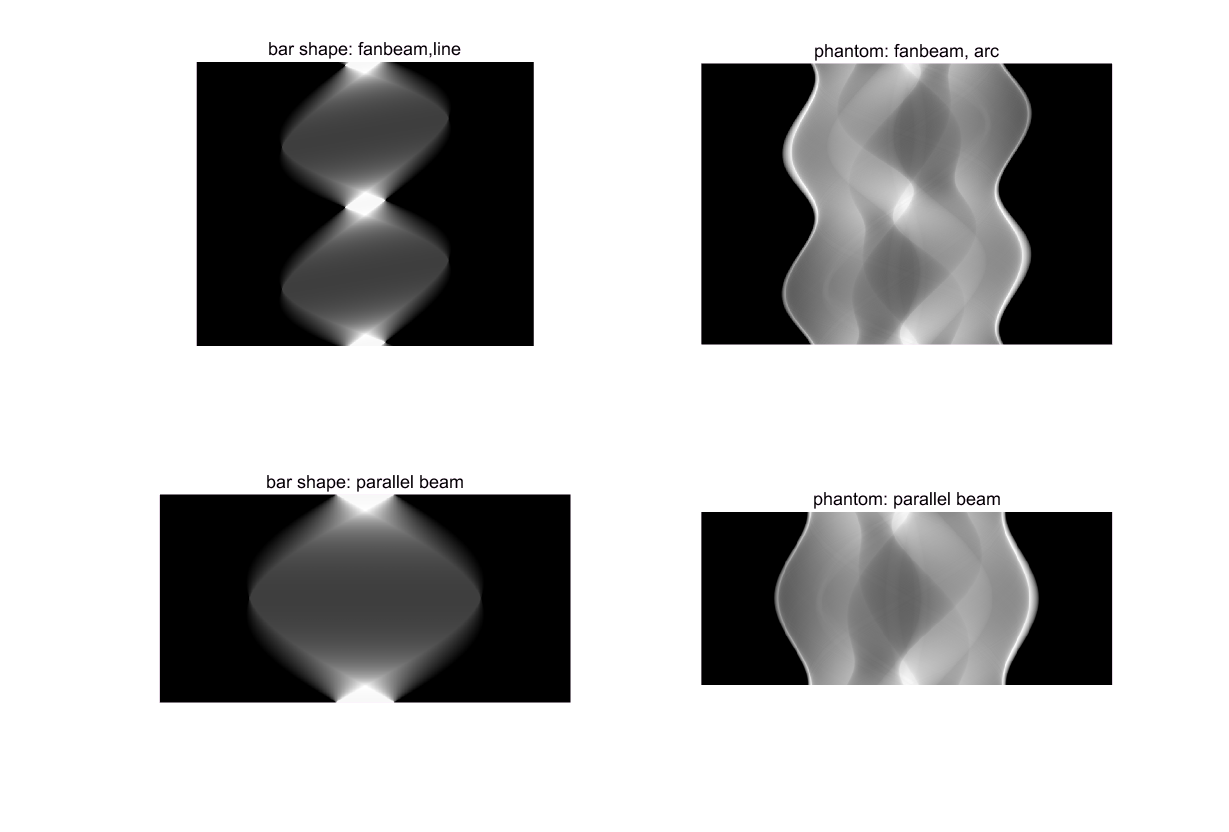

B1_line_gt = fanbeam(g1, D, 'FanSensorGeometry', 'line', 'FanSensorSpacing', 1, 'FanRotationIncrement', 0.5);
B2_arc_gt = fanbeam(g2, D, 'FanSensorGeometry', 'arc', 'FanSensorSpacing', 0.08, 'FanRotationIncrement', 0.5);
P1_line_org = fan2para(B1_line_gt, D, 'FanSensorGeometry', 'line', 'FanSensorSpacing', 1, 'FanRotationIncrement', 0.5, 'ParallelCoverage', 'halfcycle', 'ParallelRotationIncrement', 0.5, 'ParallelSensorSpacing', 1);
P2_arc_org = fan2para(B2_arc_gt, D, 'FanSensorGeometry', 'arc', 'FanSensorSpacing', 0.08, 'FanRotationIncrement', 0.5, 'ParallelCoverage', 'halfcycle', 'ParallelRotationIncrement', 0.5, 'ParallelSensorSpacing', 1);
P1_line = flipud(P1_line_org');
P2_line = flipud(P2_arc_org');
subplot(2,2,1), imshow(B1_line, []), title('bar shape: fanbeam,line');
subplot(2,2,2), imshow(B2_arc, []), title('phantom: fanbeam, arc');
subplot(2,2,3), imshow(P1_line, []), title('bar shape: parallel beam');
subplot(2,2,4), imshow(P2_line, []), title('phantom: parallel beam');

From the outcome, it is to be learned that with para2fan and fan2para, the two different data format can be converted into each other conveniently.